# **General Guide**

### **Fitting the MATLAB Logo Using Neural Networks**

The first five sections provide a detailed explanation of how to use this package. However, 

if you just want to quickly solve a data fitting problem, you can skip directly to the sixth 

section after ensuring that the data format is correct. 

In the sixth section, a simplified template is provided that allows you to quickly 

solve the problem using default parameters.

### 1. **Format Requirement**

To represent neural network computations using linear algebra notation, 

both the input data and corresponding labels should be column vectors.

For example: $f\left(x_1 ,x_2 \right):R^2 \to R^2 =\left(x_1^2 +x_2^2 ,{2x}_1^2 +x_2^2 \right)$

                                                                 
$$\begin{array}{l}
{\mathit{\mathbf{d}}}_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \;,{\mathit{\mathbf{d}}}_2 \;=\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{d}}}_N =\left\lbrack \begin{array}{c}
x_{1N} \\
x_{2N} 
\end{array}\right\rbrack \\
{\mathit{\mathbf{y}}}_1 =\left\lbrack \begin{array}{c}
1\\
3
\end{array}\right\rbrack \;,{\;\mathit{\mathbf{y}}}_2 \;=\;\left\lbrack \begin{array}{c}
5\\
9
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{y}}}_N \;=\left\lbrack \begin{array}{c}
x_{1N}^2 +x_{2N}^2 \\
{2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack 
\end{array}$$


    data : $\mathit{\mathbf{D}}\in R^{n_D \times N}$ ($n_D \times N$ Matrix), where $n_D$ is the dimension of data and $N$ is the number of data points. 

    label : $\mathit{\mathbf{Y}}\in R^{n_L \times N}$($n_L \times N$ Matrix), where $n_L$ is the dimension of label.

                                                                
$$\mathit{\mathbf{D}}=\left\lbrack \begin{array}{cccc}
1 & 1 & \cdots  & x_{1N} \\
1 & 2 & \cdots  & x_{2N} 
\end{array}\right\rbrack ,\;\;\mathit{\mathbf{Y}}=\left\lbrack \begin{array}{cccc}
1 & 5 & \cdots  & x_{1N}^2 +x_{2N}^2 \\
3 & 9 & \cdots  & {2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack$$


% Generate Data
clear; clc; close all;
n=15;
x=1:2*n+1; y=1:2*n+1;
[X,Y]=meshgrid(x,y);
V=membrane(1,n);
Predictor=[X(:),Y(:)]';
Response=V(:)';

data=Predictor;
label=Response;

### 2. Data Visualization

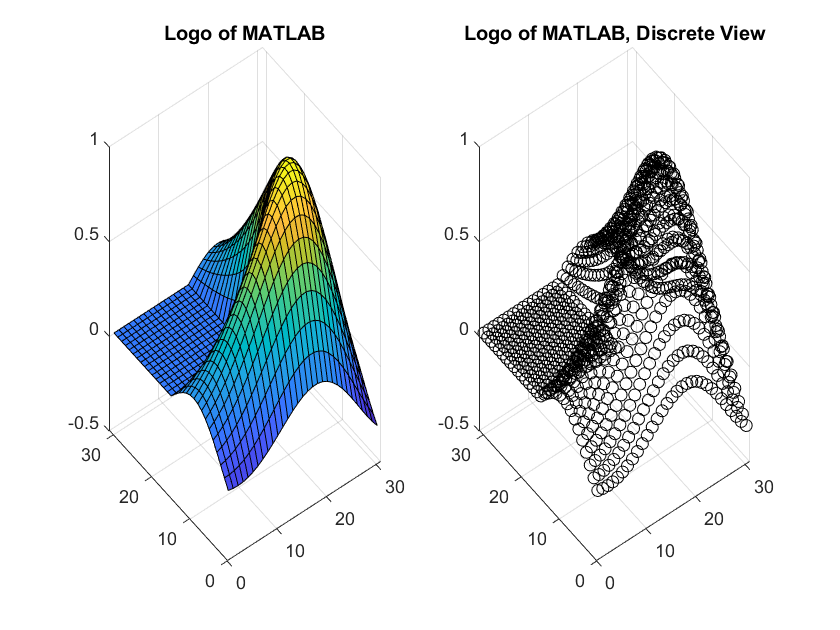

GridNumber=numel(x);
figure
subplot(1,2,1)
surf(X,Y,reshape(label,GridNumber,GridNumber))
title('Logo of MATLAB')
subplot(1,2,2)
scatter3(data(1,:),data(2,:),label,'black')
title('Logo of MATLAB, Discrete View')

Our goal is to find a surface that represents the input-output relation between the data and label.

### 3. Specify The Structure & Type of Neural Networks

The package support two types of Neural Nets for function approximation & data fitting,

the first is Multilayer Perceptron (MLP) , the second is Residual Neural Networks (ResNet).

**ResNet can make training neural networks easier, the effectiveness is particularly **

**evident when the network is very deep.**

To specify the type of network, use the command: `NN.NetworkType='ANN'` or `'ResNet'`, 

close all
NN.NetworkType='ANN'; % MLP

The logo of MATLAB is a function with 2 input 1 output, i.e.$\;f\left(\mathit{\mathbf{x}}\right):R^2 \to R$ 

Define the network structure using following command:

InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,8,8,16,OutputDimension];

**The number between Input & OutputDimension are the size of hidden layers,**

**larger hidden layer sizes and deeper networks lead to better approximation of complex functions**.

To specify the cost function to minimize using `NN.Cost`, you can choose between 

two options provided by the package: the Sum of Square Error (SSE) and the Mean Square Error (MSE).

NN.Cost='MSE'; 

You can specify the nonlinear activation function for your neural network using `NN.ActivationFunction`.

Currently, there are three built-in activation functions available, which are:

1. Gaussian 

2. Sigmoid

3. tanh

The recommended activation function for function approximation is `'Gaussian'`.

NN.ActivationFunction='Gaussian';

You can also use a function handle to define custom activation function.

When using function handles to define custom activation functions, remember to provide the derivatives as well.

% NN.ActivationFunction=@(x) exp(-x.^2);
% NN.activeDerivate=@(x) -2*x.*exp(-x.^2); % derivate of gaussian

The activation should be smooth for function approximation problems, so those commonly used activation for classification problems like 'ReLU' are not recommand.

Finally, use the command 'Initialization' to Initialize the weights & biases of NN.

NN=Initialization(LayerStruct,NN);

### 4. Solve Least Square Problem By Numerical Optimization

The standard workflow for minimizing the cost function can be separated into two stages. The first stage involves using stochastic gradient descent (SGD)-based methods to avoid getting trapped by local minima. For SGD-based algorithms, the following information is required:

#### 4.1 Stochastic Gradient Descent Based Method

option.Solver='ADAM';
option.BatchSize=100;
option.MaxIteration=100;
option.s0=5e-3; % Step Size

Start optimizing using Adaptive Momentum Estimation. (ADAM)

NN=OptimizationSolver(data,label,NN,option);

Iteration : 5 , Cost :       0.09051314 
Iteration : 10 , Cost :       0.08558799 
Iteration : 15 , Cost :       0.06834971 
Iteration : 20 , Cost :       0.05066092 
Iteration : 25 , Cost :       0.04474854 
Iteration : 30 , Cost :       0.04129055 
Iteration : 35 , Cost :       0.04241595 
Iteration : 40 , Cost :       0.03516317 
Iteration : 45 , Cost :       0.03406283 
Iteration : 50 , Cost :       0.03311103 
Iteration : 55 , Cost :       0.03122908 
Iteration : 60 , Cost :       0.02974734 
Iteration : 65 , Cost :       0.02571092 
Iteration : 70 , Cost :       0.02065702 
Iteration : 75 , Cost :       0.01853739 
Iteration : 80 , Cost :       0.01554669 
Iteration : 85 , Cost :       0.01303558 
Iteration : 90 , Cost :       0.00933385 
Iteration : 95 , Cost :       0.00843523 
Iteration : 100 , Cost :       0.00791915 
------------------------------------------------------
Max Iteration : 100 , Cost :       0.00791915 
Optimization Time :   1.1
Mean Absolute Error :   0.0649
-

#### 4.2 Quasi-Newton Method

The following information are required when using Quasi-Newton's methods.

If the infinity norm of the gradient is less than terminate condition, the optimization process will be stop.

option.Solver='BFGS';
option.MaxIteration=500;
option.TerminateCondition=1e-6;

Start optimizing using Broyden-Fletcher-Goldfarb-Shanno method (BFGS).

NN=OptimizationSolver(data,label,NN,option);

Iteration : 25 , Cost :       0.00388929 
Iteration : 50 , Cost :       0.00191131 
Iteration : 75 , Cost :       0.00092681 
Iteration : 100 , Cost :       0.00051413 
Iteration : 125 , Cost :       0.00032399 
Iteration : 150 , Cost :       0.00027219 
Iteration : 175 , Cost :       0.00022336 
Iteration : 200 , Cost :       0.00019782 
Iteration : 225 , Cost :       0.00018109 
Iteration : 250 , Cost :       0.00017306 
Iteration : 275 , Cost :       0.00015632 
Iteration : 300 , Cost :       0.00014802 
Iteration : 325 , Cost :       0.00013889 
Iteration : 350 , Cost :       0.00012694 
Iteration : 375 , Cost :       0.00011256 
Iteration : 400 , Cost :       0.00010716 
Iteration : 425 , Cost :       0.00009780 
Iteration : 450 , Cost :       0.00009194 
Iteration : 475 , Cost :       0.00008862 
Iteration : 500 , Cost :       0.00008057 
------------------------------------------------------
Max Iteration : 500 , Cost :       0.00008057 
Optimization Time :   5.9
Mean Absolute E

### 5. Quatify & Visualize Fitting Performance

Use NN.Evaluate to predict & analyzing fitting results. 

you can quatify the fitting performance  by the error vector : $\mathit{\mathbf{E}}=\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{D}}\right),\;\;\;\mathit{\mathbf{E}}\in \;R^{1\times N}$

or use the function `"FittingReport"` to quantify and visualize the performance rapidly.

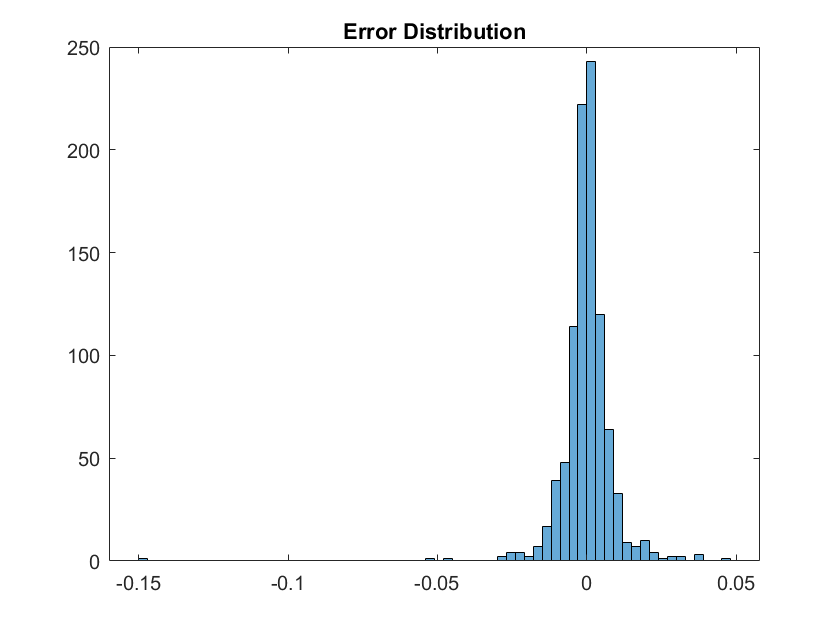

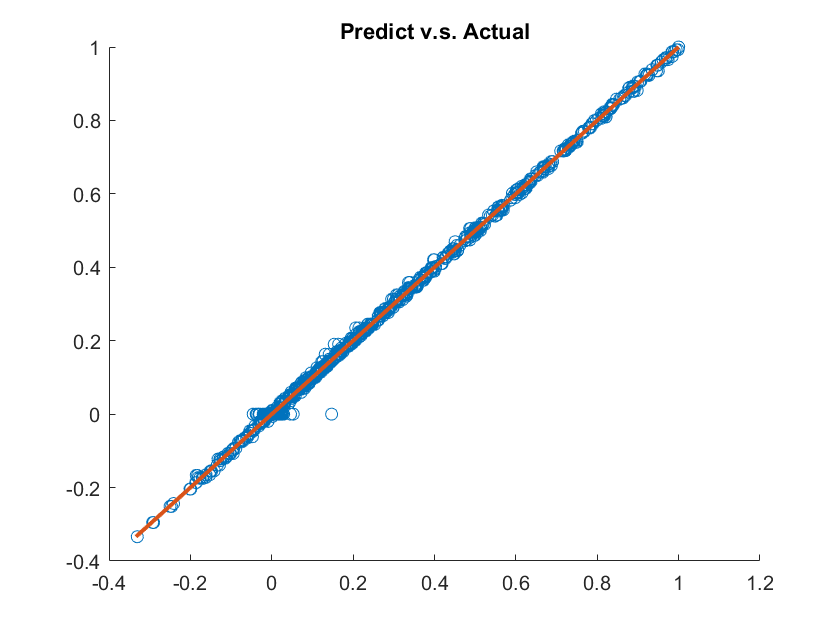

Prediction=NN.Evaluate(data);
Report=FittingReport(data,label,NN);

Visualize the optimized neural network

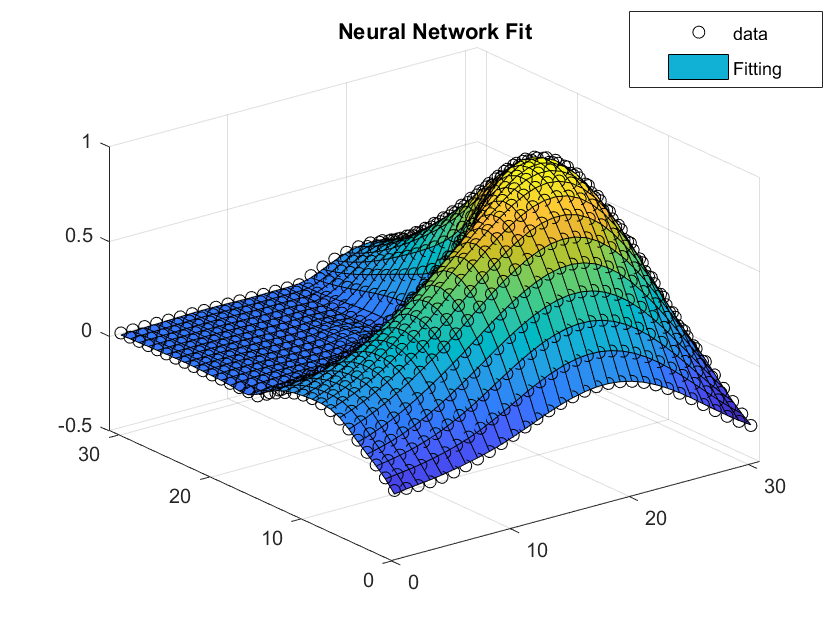

figure
scatter3(data(1,:),data(2,:),label(1,:),'black') 
hold on
[X,Y]=meshgrid(x,y);
n1=numel(x); n2=numel(y);
surf(X,Y,reshape(Prediction(1,:),n1,n2))
title('Neural Network Fit')
legend('data','Fitting')
legend("Position", [0.74834,0.86095,0.23184,0.12127])

FirstOrderOptimality=NN.FirstOrderOptimality

FirstOrderOptimality = 0.0046

The first order optimality may indicate the fitting potential of neural net, if the first order optimality is still large after optimization, you may consider using the BFGS method for further optimization of the neural network.

option.Solver='BFGS';
option.MaxIteration=100;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 5 , Cost :       0.00008051 
Iteration : 10 , Cost :       0.00008044 
Iteration : 15 , Cost :       0.00008037 
Iteration : 20 , Cost :       0.00008026 
Iteration : 25 , Cost :       0.00007980 
Iteration : 30 , Cost :       0.00007918 
Iteration : 35 , Cost :       0.00007841 
Iteration : 40 , Cost :       0.00007782 
Iteration : 45 , Cost :       0.00007703 
Iteration : 50 , Cost :       0.00007627 
Iteration : 55 , Cost :       0.00007535 
Iteration : 60 , Cost :       0.00007456 
Iteration : 65 , Cost :       0.00007416 
Iteration : 70 , Cost :       0.00007317 
Iteration : 75 , Cost :       0.00007140 
Iteration : 80 , Cost :       0.00007116 
Iteration : 85 , Cost :       0.00006992 
Iteration : 90 , Cost :       0.00006923 
Iteration : 95 , Cost :       0.00006842 
Iteration : 100 , Cost :       0.00006793 
------------------------------------------------------
Max Iteration : 100 , Cost :       0.00006793 
Optimization Time :   1.4
Mean Absolute Error :   0.0045
-

##     6. Train Neural Network Quickly with a Few Lines of Code

    Hese is the simplified template.

% Structure Set Up
InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,8,8,8,OutputDimension];
NN.Default='on';
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.Solver='Auto';
option.MaxIteration=600;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 7 , Cost :       0.06003742 
Iteration : 14 , Cost :       0.03843691 
Iteration : 21 , Cost :       0.02659603 
Iteration : 28 , Cost :       0.02090131 
Iteration : 35 , Cost :       0.01600255 
Iteration : 42 , Cost :       0.01232607 
Iteration : 49 , Cost :       0.00960153 
Iteration : 56 , Cost :       0.00752166 
Iteration : 63 , Cost :       0.00589955 
Iteration : 70 , Cost :       0.00467861 
Iteration : 77 , Cost :       0.00380853 
Iteration : 84 , Cost :       0.00318824 
Iteration : 91 , Cost :       0.00273478 
Iteration : 98 , Cost :       0.00238990 
Iteration : 105 , Cost :       0.00211894 
Iteration : 112 , Cost :       0.00189282 
Iteration : 119 , Cost :       0.00171323 
Iteration : 126 , Cost :       0.00155460 
Iteration : 133 , Cost :       0.00143457 
Iteration : 140 , Cost :       0.00132870 
Iteration : 147 , Cost :       0.00122704 
------------------------------------------------------
First Stage Optimization Finished in  150  Iteration.
---

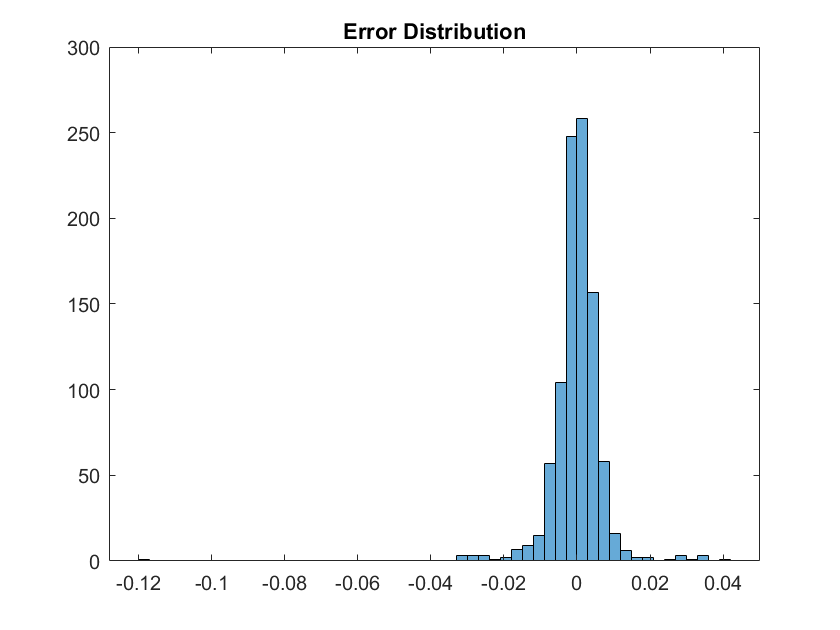

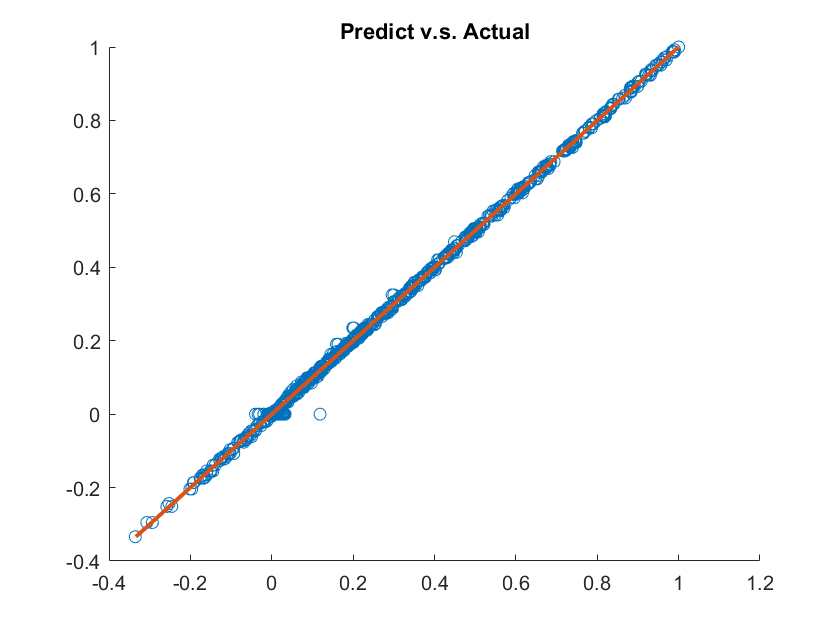

% Validate Results
Report=FittingReport(data,label,NN);